# Tutorial 5

## **Nonlinear learning models: Support Vector Machines**

### Support Vector Machines

In this part of the tutorial I would like to acknowledge a great material from the EPFL advanced machine learning class taught by Prof. Aude Billard (see for the ML_toolbox: [https://github.com/epfl-lasa/ML_toolbox](https://github.com/epfl-lasa/ML_toolbox) , for the LibSVM: [https://www.csie.ntu.edu.tw/~cjlin/libsvm/](https://www.csie.ntu.edu.tw/~cjlin/libsvm/) ).

We focus on understanding and comparing the performance of the different instances of SVM classifiers seen in class. We will begin by studying the influence of hyper-parameters of kernels used in the SVMs on 2D Datasets.

### Brief Recap

SVM is one of the most powerful nonlinear classification methods to date, as it is able to find a separating hyperplane for linearly non-separable data on a high-dimensional feature space using the kernel trick. Yet, in order for it to perform as expected, we need to find the ‘best’ hyper-parameters given the dataset at hand.  In this section we will compare the performance of different kernels on provided datasets and get acquainted with the methods which allow to choose the hyper-parameters of different kernels of interest.

Recall that in the Lecture for the linearly separable case we discussed the so-called hard-margin SVM. Whenever the assumption of linear separability of data is dropped, we considered, first, the soft-margin implementation of the SVMs allowing for slack (mistakes in classification), and, second, we introduced the so-called kernel trick, a particular instance of which for the choice of a linear kernel is the soft-margin SVM.

The optimization problem for any nonlinear feature mapping $\Phi: \mathbb{R}^d \longrightarrow \mathbb{H}$ where $\mathbb{R}^d$ is the initial feature space and $\mathbb{H}$ is a new feature space (in general, higher-dimensional, consider the discussed RKHS) can be stated as (see (1) p. 3 in the notes for Chapter 5, Part II)

(*)    $min_{\beta_0\in \mathbb{R},\bf{\beta} \in \mathbb{H}, \bf{\xi} \in \mathbb{R}^n} {\frac{1}{2} \|\beta\|_2^2 + \frac{C}{n} \sum_{i=1}^{n} \xi_i}$

                         
$${\rm subject \ to} \ y_i  (<{\bf{\beta}}, \Phi({\bf{x}}_i)> + \beta_0) \ge 1 - \xi_i, \enspace i=1,\ldots,n,\\
 \enspace\quad \quad\quad\quad\xi_i\ge0, \enspace i=1,\ldots,n,$$


where n is the number of the training examples, $\xi_i, i=1,\ldots,n$, are slack variables, and $C\in \mathbb{R}$ is a slack strength (a penalty factor used to trade-off between maximizing the margin and minimizing classification errors, $\mathbf{\beta}\in \mathbb{H}$ is is orthogonal to the separating hyperplane in the new feature space $\mathbb{H}$.

**Remark**: if one chooses $\Phi$ to be an identity map, then one gets the case of the linear kernel (linear soft-margin SVM, see see (1) p. 3 in the notes for Chapter 5, Part II). For example, in that case the constraints have the usual form of $y_i  ({\bf{\beta}}^\top{\bf{x}}_i + \beta_0) \ge 1 - \xi_i, \enspace i=1,\ldots,n$.

As we saw in class that the solution $\mathbf{\beta}^\ast\in \mathbb{H}, \beta_0^\ast\in \mathbb{R}$ (see p. 5 in the notes for Chapter 5, Part II) can be expressed as a linear combination of the training (feature) vectors:


$${\bf{\beta}}^\ast = \sum_{i=1}^{n} \mu_i^\ast y_i \Phi({\bf x}_i),\quad {{\beta}_0}^\ast = y_j -  \sum_{i=1}^{n} \mu_i^\ast y_i \Phi({\bf x}_i)^\top\Phi({\bf x}_j),$$


where $\mu_i^\ast>0$ only for the support vectors, or i.e.


$${\bf{\beta}}^\ast = \sum_{i\in\{SV\}} \mu_i^\ast y_i \Phi({\bf x}_i),\quad {{\beta}_0}^\ast = y_j -  \sum_{i\in\{SV\}} \mu_i^\ast y_i \Phi({\bf x}_i)^\top\Phi({\bf x}_j),$$


Using the kernel trick and choosing a Mercer kernel $K({\bf{x}}_i, {\bf{x}}_j) = <\Phi({\bf{x}}_i), \Phi({\bf{x}}_j)>, \enspace i,j\in\{1,\ldots,n\}$, the SVM classifier for any new point ${\bf{x}} \in \mathbb{R}^d$ is then of the following form provided that the classes are labeled in $\{-1, 1\}$ (see (3) p. 10 in the notes for Chapter 5, Part III):

$f^\ast({\bf x}) = sign\left(\sum_{i \in  \{SV\}} \mu_i^\ast y_i K({\bf x}, {\bf x}_i) + \beta_0^\ast\right)$ with $\beta_0 = y_j - \sum_{i \in  \{SV\}} \mu_i^\ast y_i K({\bf x}_i, {\bf x}_j) $,

where $\mu_i^\ast$ are obtained as maximizers the Lagrangian dual of (*).

Recall the dual problem (see p. 13 in the notes for Chapter 5, Part III; or rewrite expressions in p. 7 in the kernel formulation):

(**)       ${\rm max}_{{\bf \mu} \in \mathbb{R}^n} \mathbb{1} _n^\top {\bf \mu} - \frac{1}{2} ({\bf \mu} \circ {\bf y})^\top \mathbb{K} ({\bf \mu} \circ {\bf y})$ 

            subject to

                             
$$0 \le \mu_i\le C, i=1,\ldots,n,\\\sum_{i=1}^{n} \mu_i  y_i = 0.$$
                       

Here $\mathbb{K}\in \mathbb{S}_n$ is a Gram matrix (kernel matrix) associated to some Mercer kernel $K$ which will be chosen of a particular type depending on the dataset and the application.

There are extensions of SVMs allowing to handle multi-class problems, but in this tutorial we will be focusing on the binary case.

### **Kernel choice**

We considered in our class many examples of kernels. Here we work with the following three options:

- Homogeneous Polynomial $K({\bf x}, {\bf x}') = <{\bf x}, {\bf x}'>^p$, where p > 0 and corresponds to the polynomial degree 

- Nonhomogeneous Polynomial: $K({\bf x}, {\bf x}') = <{\bf x}, {\bf x}' + d>^p$, where p > 0 and corresponds to the polynomial degree, and d ≥ 0, common choice is d = 1

- Radial Basis Function (Gaussian): $K({\bf x}, {\bf x}') = exp\left(-\frac{ \|{\bf x}-{\bf x}'\|_2^2}{2 \sigma ^2}\right)$, where σ is the width or scale of the Gaussian kernel centered at ${\bf x}'$

### **Tuning hyper-parameters**

Depending on the kernel, one has several open hyper-parameters to choose.  For example, when using the RBF kernel, we would need to find an optimal value for both C and σ. Intuitively, C is a parameter that trades-off the misclassification of training examples against the simplicity of the decision function. The lower the C, the smoother the decision boundary (with risk of some misclassifications).  Conversely, the higher the C, the more support vectors are selected far from the margin yielding a more fitted decision boundary to the data-points.  Intuitively, σ is the radius of influence of the selected support vectors, if σ is very low, it will be able to encapsulate only those points in the feature space which are very close, on the other hand if σ is very big, the support vector will influence points further away from them.

### Example: Circle Dataset

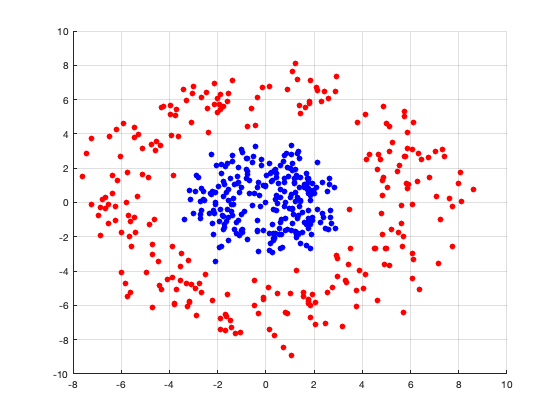

clear
[X, labels] = ml_circles_data(500, 2, 2);
X1 = X(labels == 1,:);
X2 = X(labels == 2,:);
figure
hold on
scatter(X1(:,1), X1(:,2), 'filled', 'MarkerFaceColor', 'b')
scatter(X2(:,1), X2(:,2), 'filled', 'MarkerFaceColor', 'r')
grid on


labels(labels == 2) = -1;


Support Vector Machine with linear kernel

clear options
options.svm_type = 0;   % 0: SVM
options.kernel_type = 1;% 0: Polynomial
options.C = 1;          % Cost (C \in [1,1000]) in SVM
options.degree = 1;     % degree of the polynomial 1 - linear kernel
options.coeff = 0;      % the value of d = 0
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

.....*
optimization finished, #iter = 2801
nu = 0.970833
obj = -485.377196, rho = -0.461486
nSV = 487, nBSV = 482
Total nSV = 487


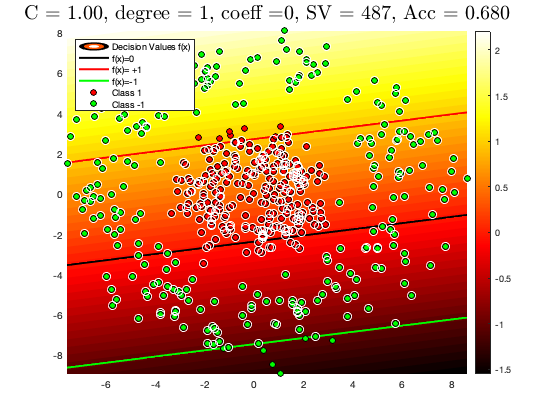

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');

Support Vector Machine with polynomial kernel of degree larger than 1

clear options
options.svm_type = 0;   % 0: SVM
options.kernel_type = 1;% 0: Polynomial
options.C = 1;          % Cost (C \in [1,1000]) in SVM
options.degree = 3;     % degree of the polynomial
options.coeff = 0;      % the value of d = 0
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

........................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................

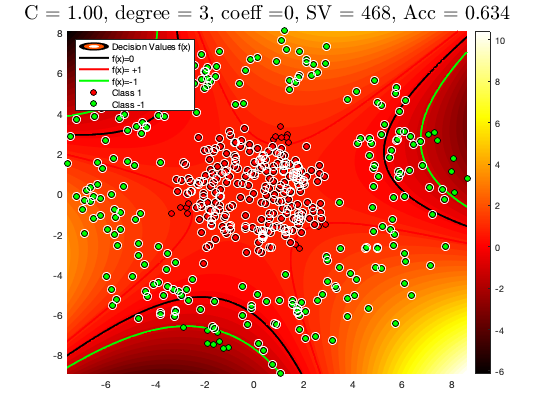

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');


clear options
options.svm_type = 0;   % 0: SVM
options.kernel_type = 1;% 0: Polynomial
options.C = 1;          % Cost (C \in [1,1000]) in SVM
options.degree = 2;     % degree of the polynomial
options.coeff = 0;      % the value of d
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

*
optimization finished, #iter = 127
nu = 0.007885
obj = -3.111322, rho = -6.736853
nSV = 5, nBSV = 2
Total nSV = 5


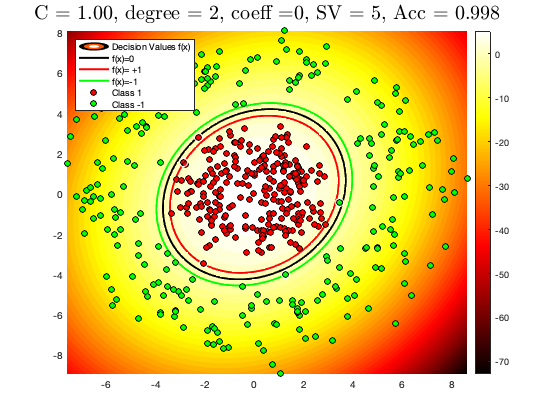

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');

Support Vector Machine with RBF kernel

% set 1 of parameters
clear options
options.svm_type = 0;   % 0: SVM
options.kernel_type = 0;% 0: RBF
options.C = 1;          % Cost (C \in [1,1000]) in SVM
options.sigma = 1;      % radial basis function parameter
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

*
optimization finished, #iter = 454
nu = 0.077266
obj = -21.480871, rho = 0.621718
nSV = 110, nBSV = 17
Total nSV = 110


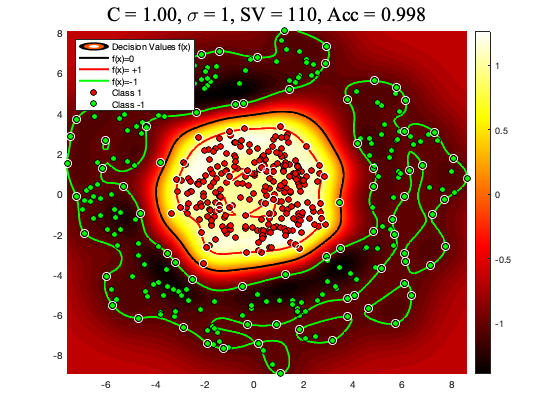

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');

% set 2 of parameters
options.C = 100;        % Cost (C \in [1,1000]) in SVM
options.sigma = 1;      % radial basis function parameter
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

*
optimization finished, #iter = 445
nu = 0.001018
obj = -25.440209, rho = 0.629152
nSV = 94, nBSV = 0
Total nSV = 94


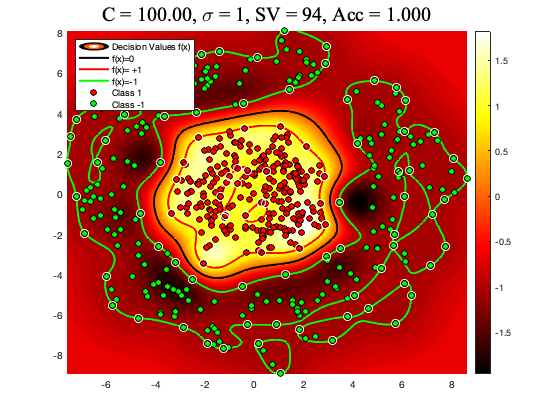

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');

% set 3 of parameters
options.C = 1000;       % Cost (C \in [1,1000]) in SVM
options.sigma = 1;      % radial basis function parameter
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

*
optimization finished, #iter = 445
nu = 0.000102
obj = -25.440209, rho = 0.629152
nSV = 94, nBSV = 0
Total nSV = 94


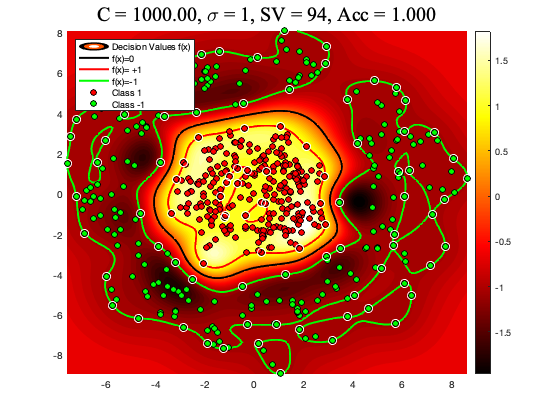

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');

% set 4 of parameters
options.C = 100;        % Cost (C \in [1,1000]) in SVM
options.sigma = 0.5;    % radial basis function parameter
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

....*
optimization finished, #iter = 2236
nu = 0.001731
obj = -43.265318, rho = 0.524775
nSV = 301, nBSV = 0
Total nSV = 301


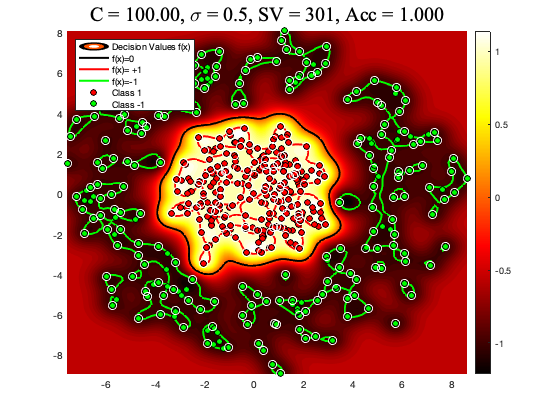

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');

% set 5 of parameters
options.C = 100;        % Cost (C \in [1,1000]) in SVM
options.sigma = 2;      % radial basis function parameter
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

*
optimization finished, #iter = 153
nu = 0.002268
obj = -56.691330, rho = 1.170893
nSV = 16, nBSV = 0
Total nSV = 16


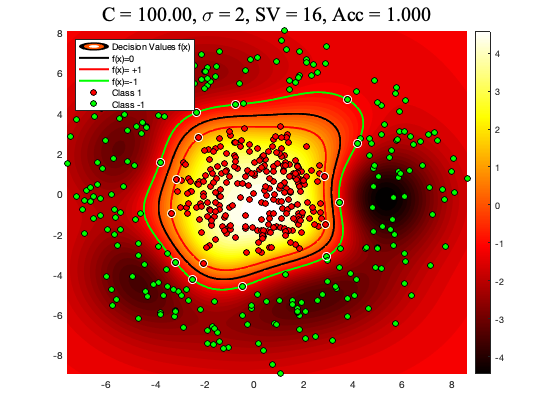

ml_plot_svm_boundary(X, labels, model, options, 'draw');

%ml_plot_svm_boundary(X, labels, model, options, 'surf');



For many combinations of C and σ a satisfactory classification is achieved (see ACC (accuracy) in the corresponding figures). We use grid search for the kernel and regularization parameters (hyper-parameters). We must choose admissible ranges for these, in the case of RBF it would be for C and �σ. Additionally, in order to get statistically relevant results one has to cross-validate with different test/train ratio. A standard way of doing this  is applying k-fold Cross Validation for each of the parameter combinations and keeping some statistics such as mean and std. deviation of the accuracy for the k runs of that specific combination of parameters, a typical number of fold is k = 10.

### Grid search of optimal hyper-parameters with cross validation 

We consider the RBF kernel. Please mind that we report everywhere the validation performance (disregard captions of figures).

% Consider C range = [1 : 500] and σ� range = [0:25 : 3]
%rng('default');
clear options
options.svm_type = 0;           % 0: SVM
options.kernel_type = 0;        % 0: RBF
options.limits_C = [1,500];     % interval for C values
options.limits_w = [0.23, 3];   % interval of kernel width \sigma
options.steps = 20;             % Step of parameter grid
options.K = 10;                 % K-fold CV parameter
options.log_grid = 1;           % log-sampled grid, set 0 for linear
Kfold = 10;

[ctest, ctrain, cranges] = ml_grid_search_class( X, labels, options );

1/20,1/20
with sigma: 0.230000 
Evaluating Param C: 1.000000  
starting K-fold Cross-Validation
 
1/10
train pts 450/ test pts 50
..*
optimization finished, #iter = 1034
nu = 0.494313
obj = -112.919535, rho = 0.318784
nSV = 401, nBSV = 23
Total nSV = 401
2/10
train pts 450/ test pts 50
..*
optimization finished, #iter = 1037
nu = 0.488719
obj = -111.798200, rho = 0.328896
nSV = 398, nBSV = 28
Total nSV = 398
3/10
train pts 450/ test pts 50
..*
optimization finished, #iter = 1109
nu = 0.486632
obj = -111.224771, rho = 0.326676
nSV = 398, nBSV = 21
Total nSV = 398
4/10
train pts 450/ test pts 50
..*
optimization finished, #iter = 1086
nu = 0.484641
obj = -110.439975, rho = 0.312477
nSV = 395, nBSV = 22
Total nSV = 395
5/10
train pts 450/ test pts 50
..*
optimization finished, #iter = 1105
nu = 0.481051
obj = -109.576454, rho = 0.323539
nSV = 394, nBSV = 22
Total nSV = 394
6/10
train pts 450/ test pts 50
..*
optimization finished, #iter = 1057
nu = 0.476606
obj = -109.298830, rho = 0.3466

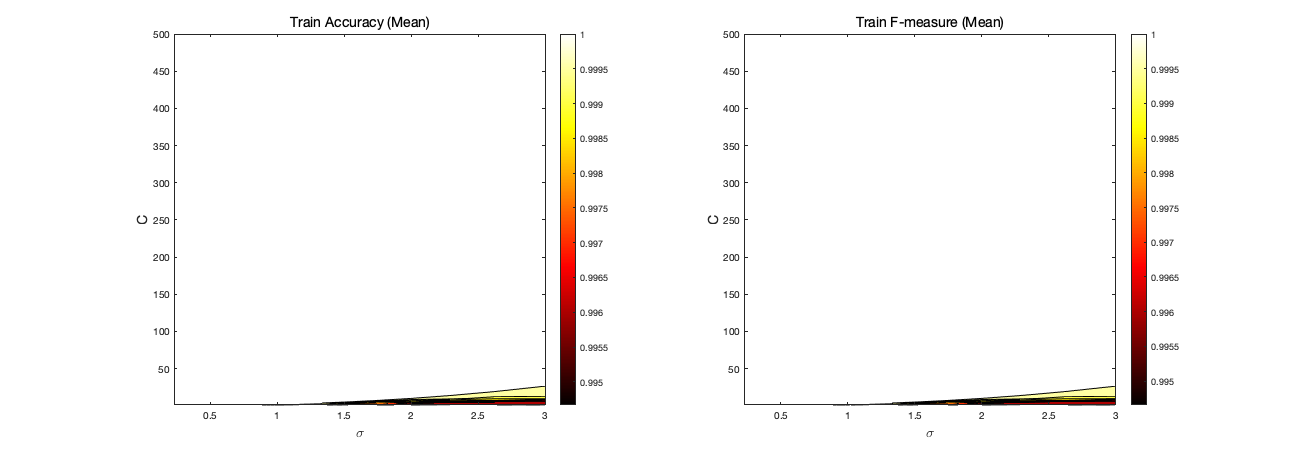

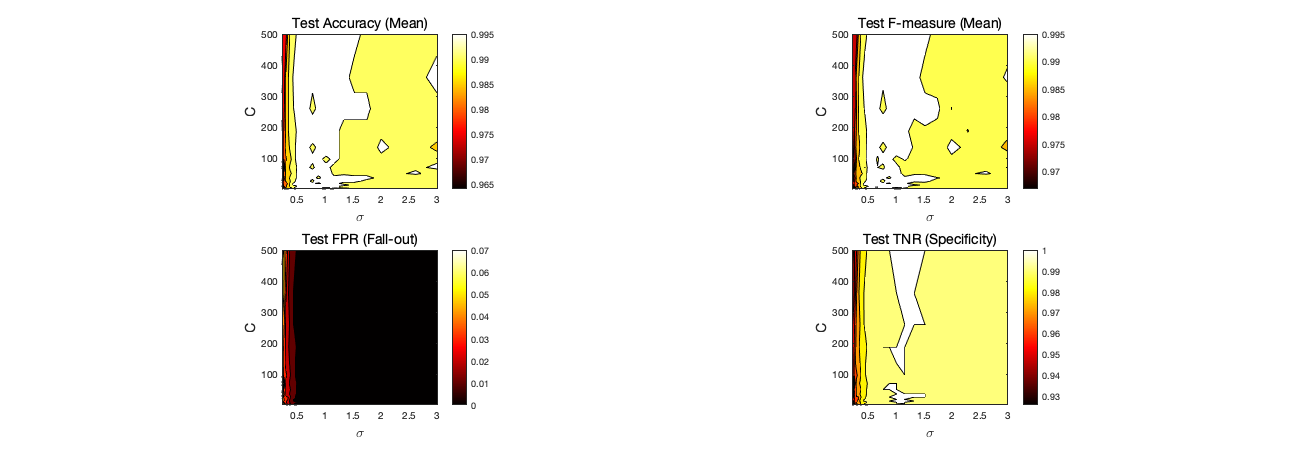


statsSVM = ml_get_cv_grid_states(ctest, ctrain);

% Plot Heatmaps from Grid Search 
cv_plot_options              = [];
cv_plot_options.title        = strcat('SVM :: ', num2str(Kfold),'-fold CV with RBF');
cv_plot_options.param_names  = {'C', '\sigma'};
cv_plot_options.metrics      = {'nmse'};
cv_plot_options.param_ranges = [cranges(1, :) ; cranges(2, :)];

parameters_used = [cranges(1, :); cranges(2, :)];

if exist('hcv','var') && isvalid(hcv)
    delete(hcv);
end
hcv = ml_plot_cv_grid_states(statsSVM,cv_plot_options);

To choose the optimal parameters, we normally ignore the metric on the training test and focus on the performance of the hyper-parameters in the validation set. However, when a classifier is showing very poor performance on the final testing or validation set, it is useful to analyze the performance on the training set. If the performance on the training set is poor, perhaps the parameter ranges are off, or you are not using the appropriate kernel or your dataset is simply not separable with this method.

Given the grid search results, how do we choose the optimal parameters?

One way of choosing the optimal hyper-parameter combination is to blindly select the iteration which yields the maximum CV ACC or F-measure.

[el_1, ind_row] = max(statsSVM.test.acc.mean);
[el_2, ind_col] = max(el_1);
i = ind_row(ind_col);
j = ind_col;

% choose parameters 
C_opt = parameters_used(1, i);
sigma_opt = parameters_used(2, j);

clear options
options.svm_type = 0;       % 0: SVM
options.kernel_type = 0;    % 0: RBF
options.C = C_opt;          % Cost (C \in [1,1000]) in SVM
options.sigma = sigma_opt;  % radial basis function parameter
% Train SVM Classifier
clear predicted_labels
clear model
[predicted_labels, model] = svm_classifier(X, labels, options, []);

....*
optimization finished, #iter = 2072
nu = 0.118873
obj = -41.320195, rho = 0.530862
nSV = 299, nBSV = 2
Total nSV = 299


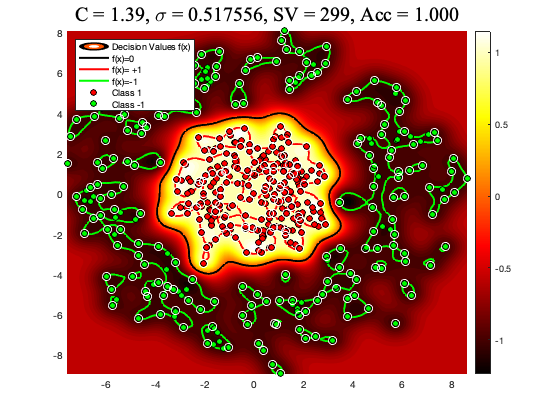

ml_plot_svm_boundary( X, labels, model, options, 'draw');

Why should we seek for the least number of support vectors? 

The number of support vectors needed to recover the decision boundary for our classifier is in fact the measure of model complexity for SVMs (see (1) p. 11, Part I Chapter 5).

Other datasets:

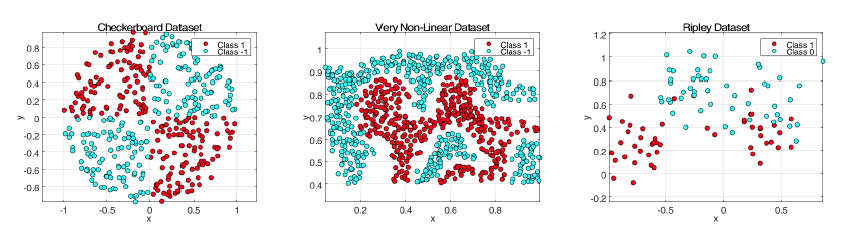

### SVM model selection with nested cross validation

See seminal paper: [http://jmlr.csail.mit.edu/papers/volume11/cawley10a/cawley10a.pdf](http://jmlr.csail.mit.edu/papers/volume11/cawley10a/cawley10a.pdf) 

We go back to my comments concerning the first two assignments.